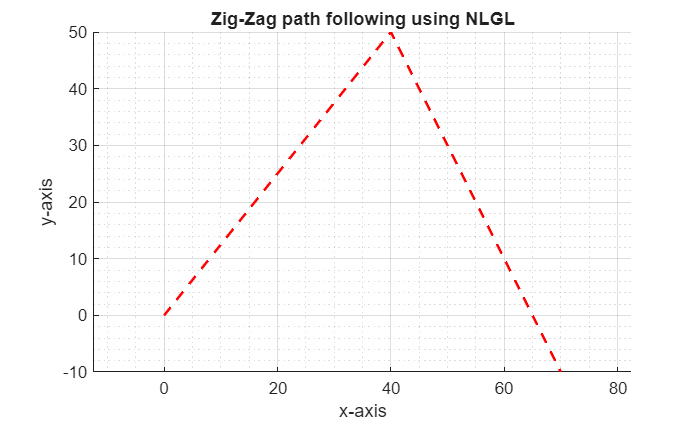

clear;
clc;

simTime = 50;
dt = 0.001;

w = [0,0;40, 50;70, -10];

figure;
hold on;
grid on; grid minor;
axis equal;
plot(w(:,1), w(:,2), "--",lineWidth=1.5, color="#ff0000");
xlabel("x-axis");
ylabel("y-axis");
title("Zig-Zag path following using NLGL");

sz = size(w);
w_sz = sz(1);
lines = zeros([w_sz-1, 2]);

for i = 1:w_sz-1
    lineSlope = (w(i,2) - w(i+1,2))/(w(i,1) - w(i+1, 1));
    lineIntercept = w(i, 2) - lineSlope*w(i,1);
    lines(i, :) = [lineSlope, lineIntercept];
end

p0 = [100, 0];   %initial Position of UAV (can change)
psi = -pi/2;        %initial heading angle of the UAV (can change)

L = 100;            %finding radius L (can change)
va = 15;            %UAV velocity (assuming constant throughout) (cna change)
back = false;        %Tracing the line backward and forward (can change)

g = 9.81;
phiMax = 45*pi/180; %radians
psiDotMax = g*tan(phiMax)/va %radians/sec

psiDotMax = 0.6540


state = zeros([simTime/dt, 5]);
state(1, :) = [p0, psi, 0, 0];
i = 2;
for t=dt:dt:simTime
    circleParams = [state(i-1,1), state(i-1, 2), L];
end

Index in position 1 is invalid. Array indices must be positive integers or logical values.



function [ptsExists, sol] = getIntersectionPts(circleParams, lineParams, back)
    if lienParams(1) == inf
        y = circleParams(2) + sqrt(circleParams(3)^2 - (lineParams(2) - circleParams(1))^2);
        x = lineParams(2);

        sol = [x, y];
        return;
    end
        a = 1 + lineParams(1)^2;
        b = 2*lineParams(1)*(lineParams(2) - circleParams(2)) - 2*circleParams(1);
        c = circleParams(1)^2 + (lineParams(2) - circleParams(2))^2 - circleParams(3)^2;
        
        D = b^2 - 4*a*c;

        if D < 0
            sol = [0, inf];
            ptsExists = false;
        else
            sgn = -1*(back) + 1*(~back); 
            x = (-b + sgn*sqrt(D))/(2*a);
            y = lineParams(1)*x + lineParams(2);
            sol = [x, y];
            ptsExists = true;
        end
end